Problem 1: Covariance Matrix Decomposition: Download historical data from yahoo for 5 years and at least 100 companies or ETFs. In this problem we will look at the covariance matrix for these assets and its properties.

clear;clc;
% data = hist_stock_data('01012014', '31122018', 'tickers.txt');
% save data.mat
load data.mat

1. Clean the data so that your input pricing matrix is as full as possible. Fill in any gaps using a reasonable method of your choice.

date = data.Date;
ticker = vertcat({data.Ticker}');
T = length(date);
K = length(ticker);
close = NaN(T, K);
for i = 1:K
    close(:,i) = data(i).AdjClose;
end
sum(sum(isnan(close))) % any NaN value?

ans = 0

    No NaN value. The data is clean.

2. Generate a sequence of daily returns for each underlying asset for each date.

ret = price2ret(close);

3. Calculate the covariance matrix of daily returns and perform an eigenvalue decomposition on the matrix. How many positive eigenvalues are there? How many were negative? We know from theory that there should be no negative eigenvalues. If any are negative, what happened?

cov_mat = cov(ret);
e = eig(cov_mat);
sum(e > 0) % count positive eigenvalues

ans = 100

sum(e < 0) % count negative eigenvalues

ans = 0

    All 100 eigenvalues are positive.

4. How many eigenvalues are required to account for 50% of the variance? How about 90%? Does this make sense to you?

K - sum(cumsum(e,'reverse')/sum(e)>0.5) + 1

ans = 5

K - sum(cumsum(e,'reverse')/sum(e)>0.9) + 1

ans = 52

    It takes 5 eigenvalues to account for 50% of the variance, and 52 ones for 90%. It makes sense according to princial component analysis (PCA). 

Problem 2: Portfolio Construction: In Lecture 6, we defined a Lagrangian for portfolio with constraints by

$L\left(\omega ,\lambda \right)=\left\langle R,\omega \right\rangle -a\left\langle \omega ,C\omega \right\rangle -\sum_{k=1}^K \lambda_k \left(\left\langle \overrightarrow{g_k } ,\omega \right\rangle -c_k \right)$     (1)

    We can rewrite it in matrix form by defining G to be the matrix whose rows are the vectors $\overrightarrow{g_k }$: $\overrightarrow{g_1 }$ is the first row of G, $\overrightarrow{g_2 }$ is the second, and so on. Also, let $\lambda$ = ($\lambda_1$ . . . , $\lambda_k$) be the vector of Lagrange multipliers, and c = (c1, . . . , cK) the vector of constraint values. Then we can rewrite (1) in matrix form:

$L\left(\omega ,\lambda \right)=\left\langle R,\omega \right\rangle -a\left\langle \omega ,C\omega \right\rangle -\left\langle \lambda ,G\omega -c\right\rangle$     (2)

1. Calculate the gradients $\nabla_{\omega } L$ and $\nabla_{\lambda } L$. (Hint: $\left\langle \lambda ,G\omega \right\rangle =\left\langle G^T \lambda ,\omega \right\rangle$).


$$\nabla_{\omega } L=R-2\mathrm{aC}\omega -G^T \lambda$$



$$\nabla_{\lambda } L=G\omega -c$$
 

2. Use $\nabla_{\omega } L$ = 0 to solve for w in terms of λ and substitute the result into the equation $\nabla_{\lambda } L$ = 0. This gives equation for λ, which for me came out to be 

$G{\mathrm{C}}^{-1} G^T \lambda =G{\mathrm{C}}^{-1} R-2\mathrm{ac}$    (3)

    where C is the covariance matrix and c is the vector of constraint values. Please don’t confuse them.

let $\nabla_{\omega } L$ = 0,  $\omega =\;\frac{1}{2a}C^{-1} \left(R-G^T \lambda \right)$

substitute into $\nabla_{\lambda } L$ = 0. $\lambda ={\left(G{\mathrm{C}}^{-1} G^T \right)}^{-1} \left(G{\mathrm{C}}^{-1} R-2\mathrm{ac}\right)$

3. Form the matrix G by imposing the budget constraint, which is $\left\langle 1,\omega \right\rangle$=1, and another constraint that allocates 10% of the portfolio to the first 17 securities (to simulate a sector allocation). Using C from Problem 1, use your favorite method and the software package of your choice to invert $G{\mathrm{C}}^{-1} G^T$ in a nice, stable way. (Hint: consider my favorite method).

C = cov_mat;
G = [ones(1,K);[ones(1,17),zeros(1,K-17)]];
pinv(G * pinv(C) * G')

ans = 	1.0e+-4 *

    0.3435   -0.0098
   -0.0098    0.0424


4. What does the resulting portfolio look like? Would it be acceptable to most mutual funds? If not, what would you to do to fix that?

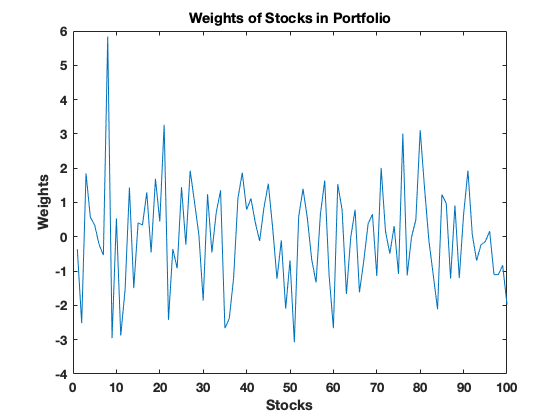

c = [1;.1];
a = 1;
R = mean(ret)';
lambda = pinv(G * pinv(C) * G') * (G * pinv(C) * R - 2 * a * c);
omega = 1/2/a * (pinv(C) * (R - G' * lambda));
myplot1(omega)

    It may not be acceptable to most mutual funds, because they might have limitations of shorting stocks. I might need to add constrains, for example, all weights need to be positive.